# **Reglerauslegung via PN-Kompensation einer Espressomaschine**

# **Matlab Controller Design via PZ Compensation for an Espresso Machine**

# 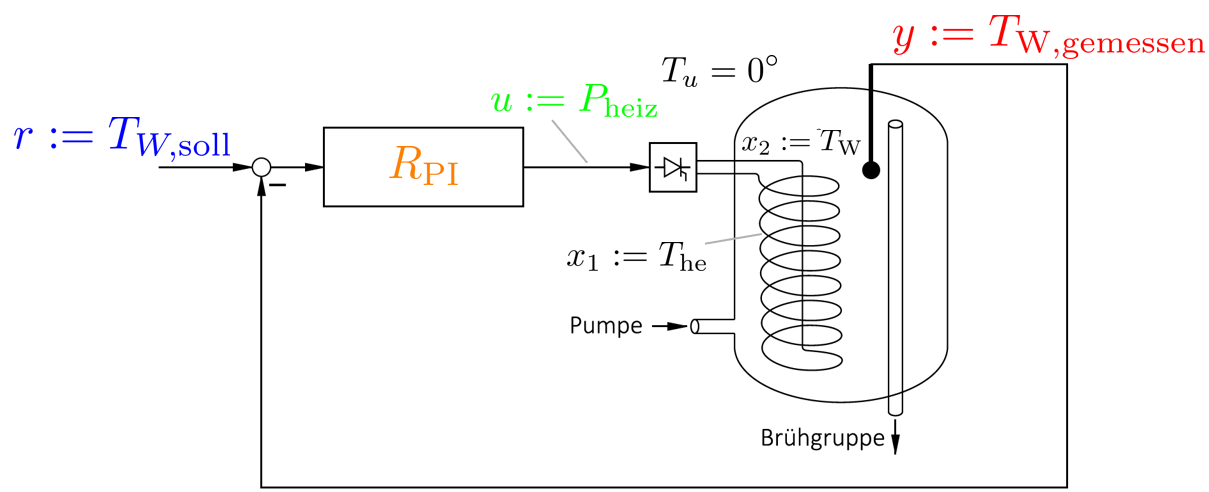                       

% Definition des PT2 Systems der Espressomaschine, und PT1 des Sensors
% Definition PT2 Systems (Heating Element plus Boiler) and Sensors (PT2)
clear
s = tf('s');
G_Esp = 630/(s^2 + 8.3*s + 1.5);    % Espressomaschine (PT2)
G_Sen = 1/(0.5*s + 1);              % Sensor (PT1)

% Pole der Esspessomaschine/ Poles of the espresso machine
p = pole(G_Esp)                     

p =    -8.1152
   -0.1848


% stationäre Verstärkung Espressomaschine / static gain espresso machine
K = dcgain(G_Esp)

K = 420

% Reduziertes PT1 Model der Espressomaschine / reduced model espresso machine
G_Esp_red = K*-p(2)/(s-(p(2)))


G_Esp_red =
 
    77.63
  ----------
  s + 0.1848
 
Continuous-time transfer function.



% PT3 Modell der Strecke (Espessomaschine mal Sensor) in Pol-Nullstellendarstellung
% PT3 model of the plant (PT2 espresso plus PT1 sensor) in pole-zero-form
G = G_Sen*G_Esp;
G = zpk(G)


G =
 
             1260
  --------------------------
  (s+8.115) (s+2) (s+0.1848)
 
Continuous-time zero/pole/gain model.



% Pole des PT3 Systems sowie Zeitkonstanten und Dämpfung
% poles of the PT3 system as well as time constants/frequ./damping
p = pole(G)

p =    -8.1152
   -2.0000
   -0.1848


damp(G)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.85e-01     1.00e+00       1.85e-01         5.41e+00    
 -2.00e+00     1.00e+00       2.00e+00         5.00e-01    
 -8.12e+00     1.00e+00       8.12e+00         1.23e-01    


% Reduzierte PT2 Strecke (reduzierte Espressomaschine mal Sensor)
% Reduced PT2 System (= reduced espresso machine times sensor model)
Gr = zpk(G_Sen*G_Esp_red)


Gr =
 
       155.26
  ----------------
  (s+2) (s+0.1848)
 
Continuous-time zero/pole/gain model.



% Pole der reduzierten Strecke (PT2) sowie Zeitkonstanten und Dämpfung (reduzierte Espressomaschine mal Sensor)
% poles of reduced PT2 system as well as time constants/frequ./damping
p = pole(Gr)

p =    -2.0000
   -0.1848


damp(Gr)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.85e-01     1.00e+00       1.85e-01         5.41e+00    
 -2.00e+00     1.00e+00       2.00e+00         5.00e-01    


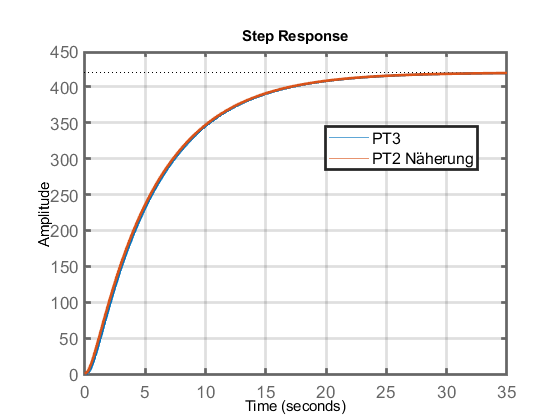

% Vergleich der reduziuerten Strecke (PT2) & Strecke (PT3) via deren Sprungantworten
% -> die Antworten sind quasi ident, weil der zweite Pol der Espressomaschine derart schnell im Vergleich zum restlichen System ist

% Step response comparison of the PT2 approximation & the full order model
% -> the responses are nearly identical, as the reduced eigenmotion vanishes pretty fast


step(G,Gr); grid on;
h=gca; h.LineWidth = 2; h.FontSize =13;
h.Children(1).Children(2).LineWidth =2; 
h.Children(2).Children(2).LineWidth =2; 
leg = legend('PT3','PT2 Näherung'); leg.Location = 'best';

## Geschlossener Kreis mit PI Regler / Closed Loop with PI Controller

% Wunschdämpfung und daraus die benötigte Verstärkung
% Desired damping and resulting controller gain (see lecture for derivation)
D=0.9;
Kr = 1/155.3/D^2

Kr = 0.0079

% Definition des PI Reglers mit I-Anteil und Nullstelle des Aufheizprozesses
% Definition of the PI controller which cancels the slowesr system pole
R_PI = Kr*(s - p(2))/s


R_PI =
 
  0.00795 s + 0.001469
  --------------------
           s
 
Continuous-time transfer function.



% (PT2-) Strecke mal Regler ungekürzt
% Open loop system (controller times PT2 plant)
L = R_PI*Gr


L =
 
  1.2343 (s+0.1848)
  ------------------
  s (s+2) (s+0.1848)
 
Continuous-time zero/pole/gain model.



% (PT2-)Strecke mal Regler gekuerzt
% Reduced Open Loop
L = minreal(L)


L =
 
  1.2343
  -------
  s (s+2)
 
Continuous-time zero/pole/gain model.



% Komplementärsensitivität / Führungsübertragung
% Complementary Sensitivity
T = minreal(L/(1+L))


T =
 
        1.2343
  ------------------
  (s^2 + 2s + 1.234)
 
Continuous-time zero/pole/gain model.



% Stationäre Verstärkung des GRK -> ist eins, also wird die vorgegebene Solltemperatur stets erreicht!
% Static gain of the closed loop -> equal 1, i.e., we are always reaching our desired temperature
K_T = dcgain(T)

K_T = 1.0000

% Pole des GRK -> Dämpfung ident zur gewählten
% Poles and Damping of the closed loop -> confirms design specifications
damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e+00 + 4.84e-01i     9.00e-01       1.11e+00         1.00e+00    
 -1.00e+00 - 4.84e-01i     9.00e-01       1.11e+00         1.00e+00    


## Analyse des Verhalten / Closed and open loop anaysis

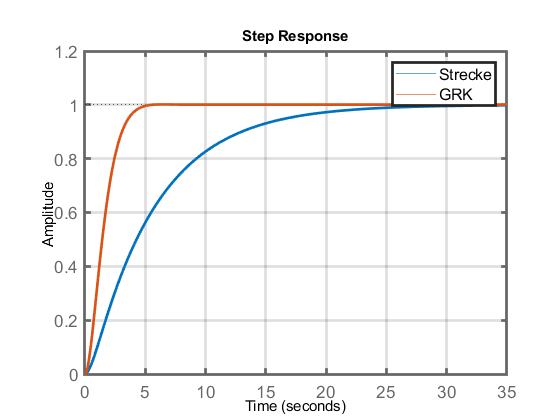

% Vergleich des dynamischen Verhaltens Strecke vs. GRK 
% Anmerkung: die Strecke ist normiert, denn die stationäre Verstaerkung ist an sich ja 420

% Comparison of open and closed loop dynamic response to step reference input
% Note: die plant is scaled to a static gain of 1 as a step would result an output of 420

step(Gr/420,T)
grid on
h=gca; h.LineWidth = 2; h.FontSize =13;
lines = findobj(gcf,'Type','Line'); set(lines,'Linewidth',2);
legend('Strecke','GRK')

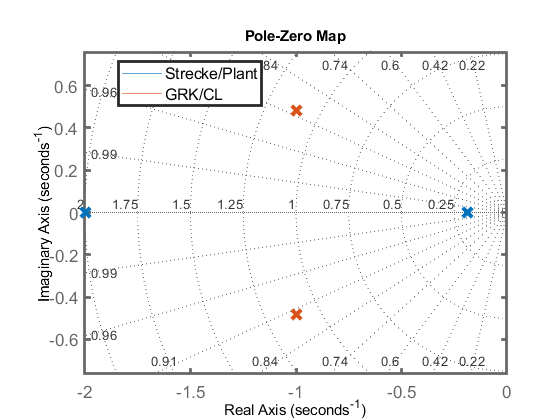

% Pole der Stecke (Sensor und PT1 Espressomaschine) sowie Pole geschlossenen Kreises (mit enstsprechner PN-Kürzung)
% Poles of the open loop and the closed loop (with PZ cancellation)
pzmap(Gr,T)
axis equal; grid on; h=gca; h.LineWidth = 2; h.FontSize =13;
h.Children(1).Children(2).MarkerSize =10; h.Children(1).Children(2).LineWidth =3;
h.Children(2).Children(2).MarkerSize =10; h.Children(2).Children(2).LineWidth =3;
leg = legend('Strecke/Plant','GRK/CL'); leg.Location = 'best';

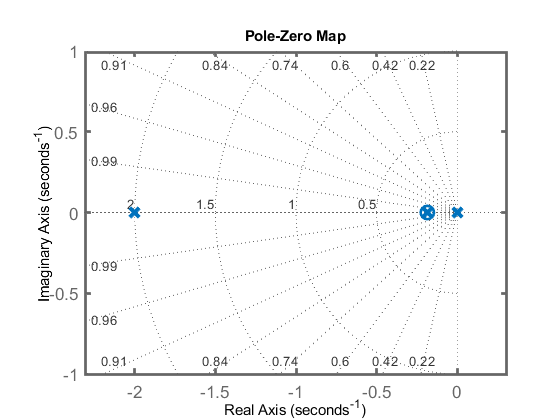

% Sichtbarkeit der PN Kompensation mit dem Regler im ORK (Strecke mal Regler)
% Illustration of  pole zero cancellation in the full (i.e. not reduced) open loop
pzmap(Gr*R_PI)
axis equal; grid on; h=gca; h.LineWidth = 2; h.FontSize =13;
h.Children(1).Children(2).MarkerSize =10; h.Children(1).Children(2).LineWidth =3;
h.Children(1).Children(1).MarkerSize =10; h.Children(1).Children(1).LineWidth =2;

## Analyse mit ungekürtzer Espressomaschine / Anlysis of the closed loop using the full order model (PT3)

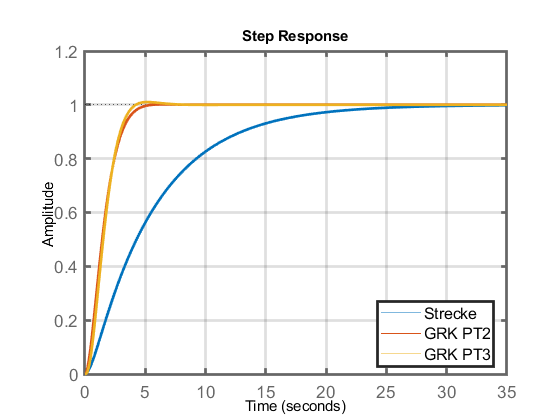

% Da der Regler am vereinfachten Modell der Espressomaschine (PT1-Näherung) ausgelegt wurde, macht es Sinn, den Regler noch am PT3 System (PT2 EM + PT1 Sensor) zu testen
% We designed the controller using a PT2 approximation; the espresso machine+sensor is, however, a PT3 system; thus we need to check to controller now on the full moedl step(Gr/420,T, feedback(R_PI*G,1))
grid on
h=gca; h.LineWidth = 2; h.FontSize =13;
lines = findobj(gcf,'Type','Line'); set(lines,'Linewidth',2);
leg=legend('Strecke','GRK PT2', 'GRK PT3'); leg.Location = 'best';

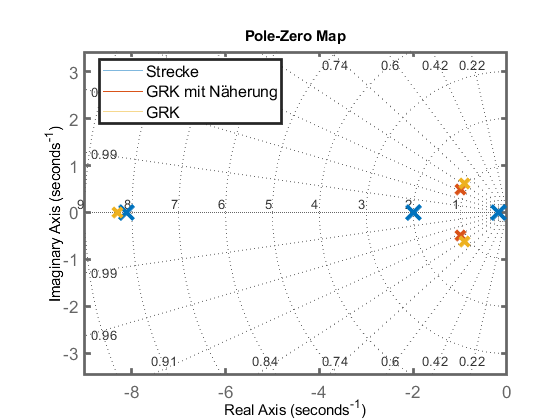

% Polstellenverschiebung durch Regler für Espressomaschine und gekürzte Espressomaschine
% Pole shoft from open to closed loop for apprxiamted and full order model.

pzmap(G,T,minreal(feedback(R_PI*G,1)))
axis equal; grid on; h=gca; h.LineWidth = 2; h.FontSize =13;
h.Children(1).Children(2).MarkerSize =10; h.Children(1).Children(2).LineWidth =3;
h.Children(2).Children(2).MarkerSize =10; h.Children(2).Children(2).LineWidth =3;
h.Children(3).Children(2).MarkerSize =15; h.Children(3).Children(2).LineWidth =3;
leg = legend('Strecke', 'GRK mit Näherung', 'GRK'); leg.Location = 'best';